# cl5 DOF robot


% Lengder
L1 = 0.92; L2 = .72; L3 = .16;
d1 = 0.35; 

L(1) = Link('d',d1,'a',0,'alpha',-pi/2);

Unrecognized function or variable 'Link'.

L(2) = Link('d',0,'a',L1,'alpha',0);
L(3) = Link('d',0,'a',L2,'alpha',0);
L(4) = Link('d',0,'a',0,'alpha',-pi/2);
L(5) = Link('d',L3,'a',0,'alpha',0);
L;
% DH parameter tabell
Gruppebot = SerialLink(L,'name','GruppeBot')
% Tar høyde for 200mm for gripperfeste og 30mm ned til senter på sugekoppene
% Antar at senter ligger 30mm bak feste til gripperen
Gruppebot.tool = transl(0.17,0,0.03)

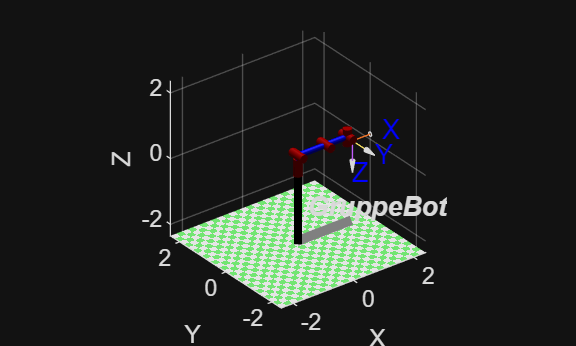


Gruppebot.plot([0 0 0 0 0])

Gruppebot.fkine([0 0 0 0 0])

 

ans = 
         1         0         0      1.81
         0        -1         0         0
         0         0        -1      0.16
         0         0         0         1
